# Hold-out validation of TA2445 model

## Open the model

modelName = 'TA2445';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','0')

## Estimation problem

You use measured data to estimate the model parameters.

Input is IPTG concentration (step).

Measured output data is concentation in the culture medium

- OD600

- IPA

## Define the estimation experiments

Load the measured data.

outputData = cell(15,1);
for expIdx = 1:15
    outputData{expIdx} = readtable("TA2445Data.xlsx","Sheet",expIdx);
end

Create the input data.

inputTime = [0 51.5]';
input = cell(15,1);

for i = 0:4
    input{5*i + 1} = 0.01*[1 1]';
    input{5*i + 2} = 0.03*[1 1]';
    input{5*i + 3} = 0.05*[1 1]';
    input{5*i + 4} = 0.1*[1 1]';
    input{5*i + 5} = 1.0*[1 1]';
end

inputData = cell(15,1);
for expIdx = 1:15
    inputData{expIdx} = table;
    inputData{expIdx}.Time = inputTime;
    inputData{expIdx}.IPTG = input{expIdx};
end

Create an experiment object to store the measured input/output data. 

Exp = sdo.Experiment(modelName);
% sdo.Experiment object
% The OutputData property and other properties are empty

Create Simulink.SimulationData.Signal objects to store the measured outputs.

% IPTG input
IPTGSignal = Simulink.SimulationData.Signal;
IPTGSignal.Name = 'IPTG';
IPTGSignal.BlockPath = modelName + "/IPTG";
IPTGSignal.PortType  = 'inport';
IPTGSignal.PortIndex = 1;
IPTGSignal.Values    = timeseries(inputData{1}.IPTG,inputData{1}.Time);

Exp.InputData = IPTGSignal; % add the signal object to the experiment

% OD600 output
OD600Signal = Simulink.SimulationData.Signal;
OD600Signal.Name = 'OD600';
OD600Signal.BlockPath = modelName + "/Gain";
OD600Signal.PortType = 'outport';
OD600Signal.PortIndex = 1;
OD600Signal.Values = timeseries(outputData{1}.OD600,outputData{1}.Time);

% Glucose output
% GlucoseSignal = Simulink.SimulationData.Signal;
% GlucoseSignal.Name = 'Glucose';
% GlucoseSignal.BlockPath = modelName + "/Gain2";
% GlucoseSignal.PortType = 'outport';
% GlucoseSignal.PortIndex = 1;
% GlucoseSignal.Values = timeseries(outputData{1}.Glucose,outputData{1}.Time);

% IPA output
IPASignal = Simulink.SimulationData.Signal;
IPASignal.Name = 'IPA';
IPASignal.BlockPath = modelName + "/Demux";
IPASignal.PortType = 'outport';
IPASignal.PortIndex = 5;
IPASignal.Values = timeseries(outputData{1}.IPA,outputData{1}.Time);

Exp.OutputData = [OD600Signal; IPASignal]; % add the signal object to the experiment

Define the five experiments.

Exp = [Exp;Exp;Exp;Exp;Exp;...
        Exp;Exp;Exp;Exp;Exp;...
        Exp;Exp;Exp;Exp;Exp];
for expIdx = 1:15
    Exp(expIdx).InputData.Values = timeseries(inputData{expIdx}.IPTG,inputData{expIdx}.Time);
    Exp(expIdx).OutputData(1).Values = timeseries(outputData{expIdx}.OD600,outputData{expIdx}.Time);
    % Exp(expIdx).OutputData(2).Values = timeseries(outputData{expIdx}.Glucose,outputData{expIdx}.Time);
    Exp(expIdx).OutputData(2).Values = timeseries(outputData{expIdx}.IPA,outputData{expIdx}.Time);
end

## Specify the parameters to estimate

Specify bounds for the parameter values based on the structure of the model.

parameters = readtable("Parameters_TA2445.xlsx");
p = sdo.getParameterFromModel(modelName,parameters.Name);

% the output argument 'p' is a Param.Continuous object
% scaling factor can be specified in the Param.Continuous object

for paramIdx = 1:height(parameters)
    p(paramIdx).Value = parameters.InitialGuess(paramIdx);
    p(paramIdx).Minimum = parameters.Minimum(paramIdx);
    p(paramIdx).Maximum = parameters.Maximum(paramIdx);
    p(paramIdx).Scale = parameters.Scale(paramIdx);
    p(paramIdx).Free = parameters.Free(paramIdx);
end

## Compare the measured output and the simulated output with the initial guess

Set the initial guess of the parameters to the experiment object and simulate. 

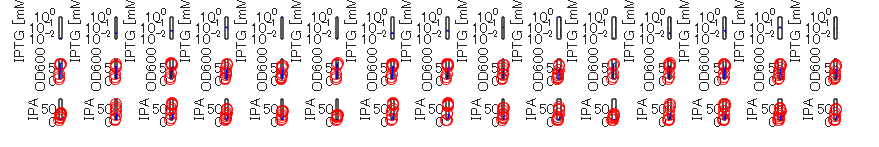

Exp = setEstimatedValues(Exp,p);
figure('Position', [100 100 1500 250]);
t = tiledlayout(3,15,'Padding','Compact','TileSpacing','tight');
t.TileIndexing = 'columnmajor';
for expIdx = 1:15
    plotSimTA2445(Exp,expIdx);
end

Check the objective function.

Simulator = createSimulator(Exp(1));
Error = estimation_Objective(p,Simulator,Exp,1:15,1:2,0);
fx = Error.F'*Error.F

fx = 41.0936

## Configure the simulator and model for Fast Restart

The simulator controls whether the model is simulated using fast restart or not. The `fastRestart` command is used to configure the simulator to use Fast Restart. 

The model uses a variable-step solver, and may not output values at the times in the measured experiment data. To output values at the times of the measured data, use the `set_param` command to specify the model logging output times as a workspace variable. In the estimation objective function, the variable is then used to specify output times to be the same as the measured experiment data. The model `OutputTimes` is set before configuring the simulator for fast restart, as once the model is configured for fast restart, the model logging configuration can not change.

Simulator = createSimulator(Exp(1));
modelName = Simulator.ModelName;
set_param(modelName,'OutputOption','SpecifiedOutputTimes', ...
    'OutputTimes','OutputTimesValues');
% 'OutputTimesValues' will be created in the objective function and assigned to the base
% workspace
Simulator = fastRestart(Simulator,'on');

The simulator can now be used during estimation, and the model will be simulated using fast restart.

## Define the estimation objective function

Create an estimation objective function to evaluate how closely the simulation output, generated using the estimated parameter values, matches the measured data.

Use an anonymous function with one input argument that calls the `cellCultureModel_Objective` function. Pass the anonymous function to `sdo.optimize`, which evaluates the function at each optimization iteration.

lambda = 0;         % regularization parameter
expToUse = 1:15;     % training data set
outputToUse = 1:2;  % two outputs (OD600,IPA)
% estFcn = @(p) estimation_Objective(p,Simulator,Exp,expToUse,outputToUse,lambda);

## Estimate the parameters

Use the `sdo.optimize` function to estimate the actuator parameter values and initial state. 

Specify the optimization options. The estimation function `sdoAircraftEstimation_Objective` returns the error residuals between simulated and experimental data and does not include any constraints, making this problem ideal for the `lsqnonlin` solver.

options = sdo.OptimizeOptions;
options.Method = 'lsqnonlin';
options.UseParallel = 1;
options.OptimizedModel = modelName;

Create a cluster object

% close the model!
c = parcluster

c = 

 Generic Cluster

    プロパティ: 

                   Profile: cc21dev0_cluster_short R2022a
                  Modified: false
                      Host: LAPTOP-5PV3VUVE
                NumWorkers: 100
                NumThreads: 1

        JobStorageLocation: C:\Users\tomok\AppData\Roaming\MathWorks\MATLAB\3p_cluster_jobs\default_cluster\LAPTOP-5PV3VUVE\R2022a\nonshared
         ClusterMatlabRoot: /usr/local/MATLAB/R2022a/
           OperatingSystem: unix

   RequiresOnlineLicensing: false
     PluginScriptsLocation: C:\Users\tomok\MATLAB\slurm_integration\IntegrationScripts\default_cluster
      AdditionalProperties: 

Create a job and submit it to the cluster. 

pathToData = pwd

pathToData = 'C:\Users\tomok\MATLAB\Projects\Soma2014'

for condIdx = 1:3
    job(condIdx) = batch(c,@parallelEstimation,2,{p,options,Exp,Simulator,condIdx}, ...
                "Pool",6, ...
                "CurrentFolder",'.', ...
                "AdditionalPaths",pathToData, ...
                "AttachedFiles",{'TA2445.slx'} ...
                );
end

additionalSubmitArgs = '--ntasks=7 --cpus-per-task=1 --ntasks-per-core=1 --mem-per-cpu=7300MB -p cluster_short --time 4:00:00'

additionalSubmitArgs = '--ntasks=7 --cpus-per-task=1 --ntasks-per-core=1 --mem-per-cpu=7300MB -p cluster_short --time 4:00:00'

additionalSubmitArgs = '--ntasks=7 --cpus-per-task=1 --ntasks-per-core=1 --mem-per-cpu=7300MB -p cluster_short --time 4:00:00'

Check the state of the job.

for condIdx = 1:3 % change manually!
    sprintf('job %d is %s \n',condIdx ,job(condIdx).State)
    diary(job(condIdx))
end

ans =     'job 1 is finished 
     '


--- ダイアリ開始 ---

modelName =

    'TA2445'


validSet =

     1     6    11


trainSet =

     2     3     4     5     7     8     9    10    12    13    14    15

Configuring parallel workers for optimization...
Parallel workers configured for optimization.

 Optimization started 21-Feb-2023 22:20:09

                                          First-order 
 Iter F-count        f(x)      Step-size  optimality
    0     21      31.2372            1                                         
    1     42      12.6873       0.5803         7.92
    2     63      6.40048       0.6344         1.24
    3     84       5.7888       0.8562         20.6
    4    105      4.40079      0.06343         1.49
    5    126       4.0269        0.214         1.73
    6    147      3.62421       0.1589        0.246
    7    168      3.55645        0.214        0.245
    8    189      3.52606       0.1649        0.256
    9    210      3.52435     0.003129       0.0858
Local minimum possible.

lsqnonlin stoppe

ans =     'job 2 is finished 
     '


--- ダイアリ開始 ---

modelName =

    'TA2445'


validSet =

     2     7    12


trainSet =

     1     3     4     5     6     8     9    10    11    13    14    15

Configuring parallel workers for optimization...
Parallel workers configured for optimization.

 Optimization started 21-Feb-2023 22:20:12

                                          First-order 
 Iter F-count        f(x)      Step-size  optimality
    0     21      35.3606            1                                         
    1     42      11.7805       0.6646         9.62
    2     63      7.52177       0.6556         1.44
    3     84      6.10779        1.243         2.38
    4    105       5.9156        1.261         9.91
    5    126      5.41103      0.03267         1.16
    6    147      5.40909    0.0008655         1.01
Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.
Removing data from paralle

ans =     'job 3 is finished 
     '


--- ダイアリ開始 ---

modelName =

    'TA2445'


validSet =

     3     8    13


trainSet =

     1     2     4     5     6     7     9    10    11    12    14    15

Configuring parallel workers for optimization...
Parallel workers configured for optimization.

 Optimization started 21-Feb-2023 22:20:16

                                          First-order 
 Iter F-count        f(x)      Step-size  optimality
    0     21      30.6242            1                                         
    1     42      9.67431       0.7102         8.22
    2     63      6.03425       0.6891         1.13
    3     84      4.88864        1.235         2.82
    4    105      4.40346       0.2212        0.723
    5    126      4.16463       0.4607         40.9
    6    147      4.10946       0.1416        0.662
    7    168      4.10899    0.0004882       0.0488
Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value o

Get the printed log in the cluster.

% getReport(job.Tasks(1).Error)

Fetch the results from the cluster.

for condIdx = 1:3 % change manually!
    if job(condIdx).State == "finished"
        result = fetchOutputs(job(condIdx));
        pOpts_TA2445{condIdx,1} = result{1};
        optInfos_TA2445{condIdx,1} = result{2};
    end
end

Save the optimized parameters and the optimization report.

save('pOpts_TA2445','pOpts_TA2445')
save('optInfos_TA2445','optInfos_TA2445')

Delete the job from the cluster.

delete(job)

Clear the job object from the base workspace of the client.

clear job

## Restore the model

Restore the simulator fast restart settings. This clears the logging and other settings used for the optimization problem. 

Simulator = fastRestart(Simulator,'off');
set_param(modelName,'OutputOption','RefineOutputTimes','OutputTimes','[]');

## Calculate coefficient of determination (R2)

Simulator = createSimulator(Exp(1));
R2_TA2445 = zeros(15,2);
for expIdx = 1:15 % test data set
    condIdx = mod(expIdx + 4,5) + 1
    R2_TA2445(expIdx,:) = rSquared(pOpts_TA2445{condIdx,1},Simulator,Exp,expIdx,1:2);
end

condIdx = 1

condIdx = 2

condIdx = 3

condIdx = 4

condIdx = 5

condIdx = 1

condIdx = 2

condIdx = 3

condIdx = 4

condIdx = 5

condIdx = 1

condIdx = 2

condIdx = 3

condIdx = 4

condIdx = 5

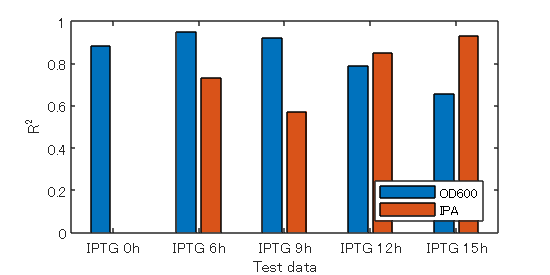


R2_TA2445_OD600 = R2_TA2445(:,1);
R2_TA2445_IPA = R2_TA2445(:,2);

R2_TA2445_OD600_mean = mean(reshape(R2_TA2445_OD600,5,3),2);
R2_TA2445_IPA_mean = mean(reshape(R2_TA2445_IPA,5,3),2);

% all conditions
figure('Position', [100 100 400 200]);
b = bar([R2_TA2445_OD600_mean,R2_TA2445_IPA_mean]);
xticklabels({'IPTG 0h' 'IPTG 6h' 'IPTG 9h' 'IPTG 12h' 'IPTG 15h'})
xlabel('Test data')
ylabel('R^2')
ylim([0 1])
legend({'OD600' 'IPA'},'Location','Southeast')

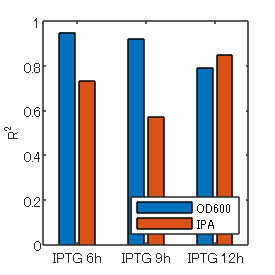

% interpolation conditions
figure('Position', [100 100 200 200]);
b = bar([R2_TA2445_OD600_mean(2:4),R2_TA2445_IPA_mean(2:4)]);
xticklabels({'IPTG 6h' 'IPTG 9h' 'IPTG 12h'})
% xlabel('Test data')
ylabel('R^2')
ylim([0 1])
legend({'OD600' 'IPA'},'Location','Southeast')

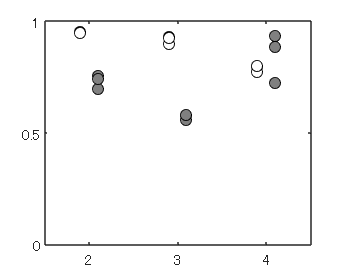

cond = [1:5,1:5,1:5]';
d = 0.1;

figure('Position', [100 100 250 200]);
plot(cond-d,R2_TA2445_OD600,'ko','MarkerFaceColor','w')
hold on
plot(cond+d,R2_TA2445_IPA,'ko','MarkerFaceColor',[0.5 0.5 0.5])
xlim([1.5 4.5])
xticks([2 3 4])
ylim([0 1])
yticks([0 0.5 1])
hold off

% sdo.setValueInModel('TA1415',pOpt);

Close the model.

bdclose(modelName)

*Copyright Tomoki Ohkubo@NAIST*